%Luenberger Observer for Linear System
clc;
clear all;
close all;
[A,B,Q,R] = AB();
%From the observability check, we got that only C_1, C_3, C_4 are
%observable.

[C_1,C_3,C_4] = get_C_matrices();

eig(A)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.7282i
  -0.0000 - 0.7282i
   0.0000 + 1.0425i
   0.0000 - 1.0425i


req_poles1 = [-10;-20;-30;-40;-50;-60];
req_poles2 = [-10;-20;-30;-40;-50;-50];
req_poles3 = [-10;-20;-30;-50;-50;-50];
% We get Luenberger Observer matrix for each C when we try place the poles at the required position.
% We also know that placing poles for (A,C)' will give same
% poles for (A,C)
rank(C_1)

ans = 1

rank(C_3)

ans = 2

rank(C_4)

ans = 3

% We can place poles only with multiplicity of rank(C) matrices. Otherwise,
% we cannot place the poles at the required positions. Generally, the poles
% of the estimate (observer) should go faster than the system. Hence, we
% choose multiplicity of 10 for the pole placement.
Luenberger1 = place(A',C_1',req_poles1);
L1 = Luenberger1'

L1 = 	1.0e+09 *

    0.0000
    0.0000
   -0.3666
   -1.4828
    0.3658
    1.4663


Luenberger3 = place(A',C_3',req_poles2);
L3 = Luenberger3'

L3 = 	1.0e+05 *

    0.0012   -0.0000
    0.0491   -0.0004
   -0.7979    0.0189
   -4.0854    0.2428
    0.0000    0.0008
    0.0033    0.0149


Luenberger4 = place(A',C_4',req_poles3);
L4 = Luenberger4'

L4 = 	1.0e+03 *

    0.0798   -0.0019    0.0001
    1.4908   -0.0959    0.0062
   -0.0019    0.0602   -0.0000
   -0.0949    0.5086   -0.0006
    0.0001   -0.0000    0.0700
    0.0072   -0.0007    0.9990


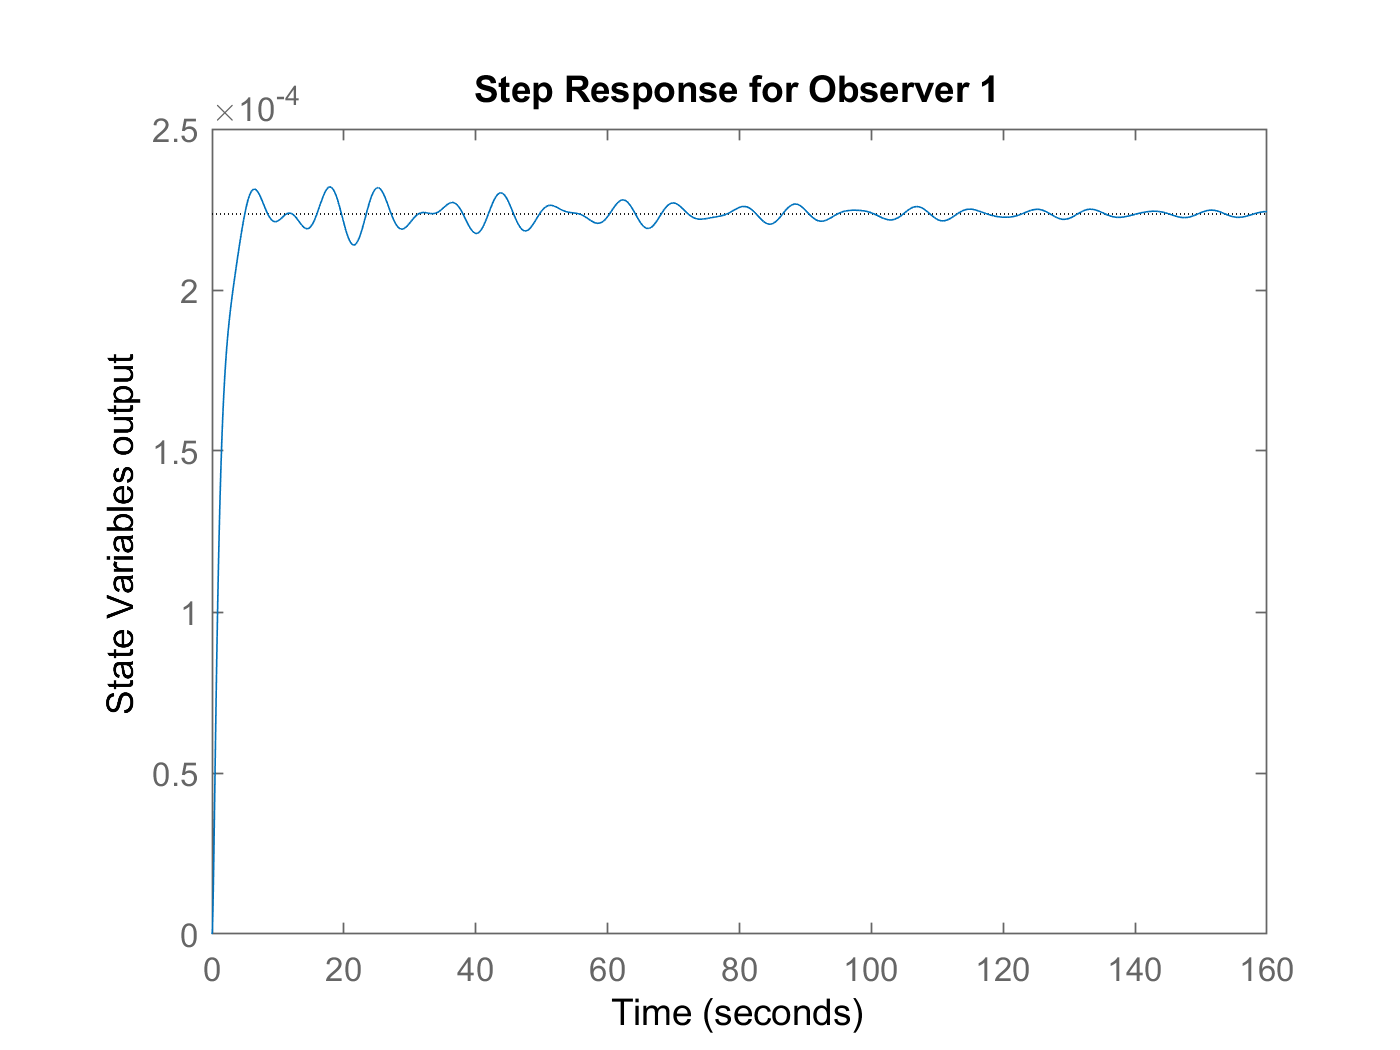


[K,P,Poles] = lqr(A,B,Q,R);
%Defining the state-space matrices for Linearized system with observer
%As mentioned in the class notes, The closed loop system has [x;x_hat] =
%[Ak BK;0 A-LC] Only difference is that we took feedback as -KX insted of
%KX
%X_hat has 6 state estimates. Hence each of the matrix element has 6 columns, 6 rows 
AL1 = [(A-B*K) B*K;zeros(size(A)) (A-L1*C_1)];
% size(AL1)
BL1 = [B;zeros(size(B))];
%Because in the output we are observing the required state variables. 
CL1 = [C_1 zeros(size(C_1))];
DL1 = 0;

AL3 = [(A-B*K) B*K;zeros(size(A)) (A-L3*C_3)];
% size(AL3)
BL3 = [B;zeros(size(B))];
%Because in the output we are observing the required state variables. 
CL3 = [C_3 zeros(size(C_3))];
DL3 = 0;
AL4 = [(A-B*K) B*K;zeros(size(A)) (A-L4*C_4)];
% size(AL4)
BL4 = [B;zeros(size(B))];
%Because in the output we are observing the required state variables. 
CL4 = [C_4 zeros(size(C_4))];
DL4 = 0;
initial_state = [3,0.3,20,1,10,2,0,0,0,0,0,0]; %last 6 colums specify the initial state of the observer estimate which is zero
statespace1 = ss(AL1,BL1,CL1,DL1);
statespace3 = ss(AL3,BL3,CL3,DL3);
statespace4 = ss(AL4,BL4,CL4,DL4);
figure
step(statespace1)
title('Step Response for Observer 1')
xlabel('Time')
ylabel('State Variables output')

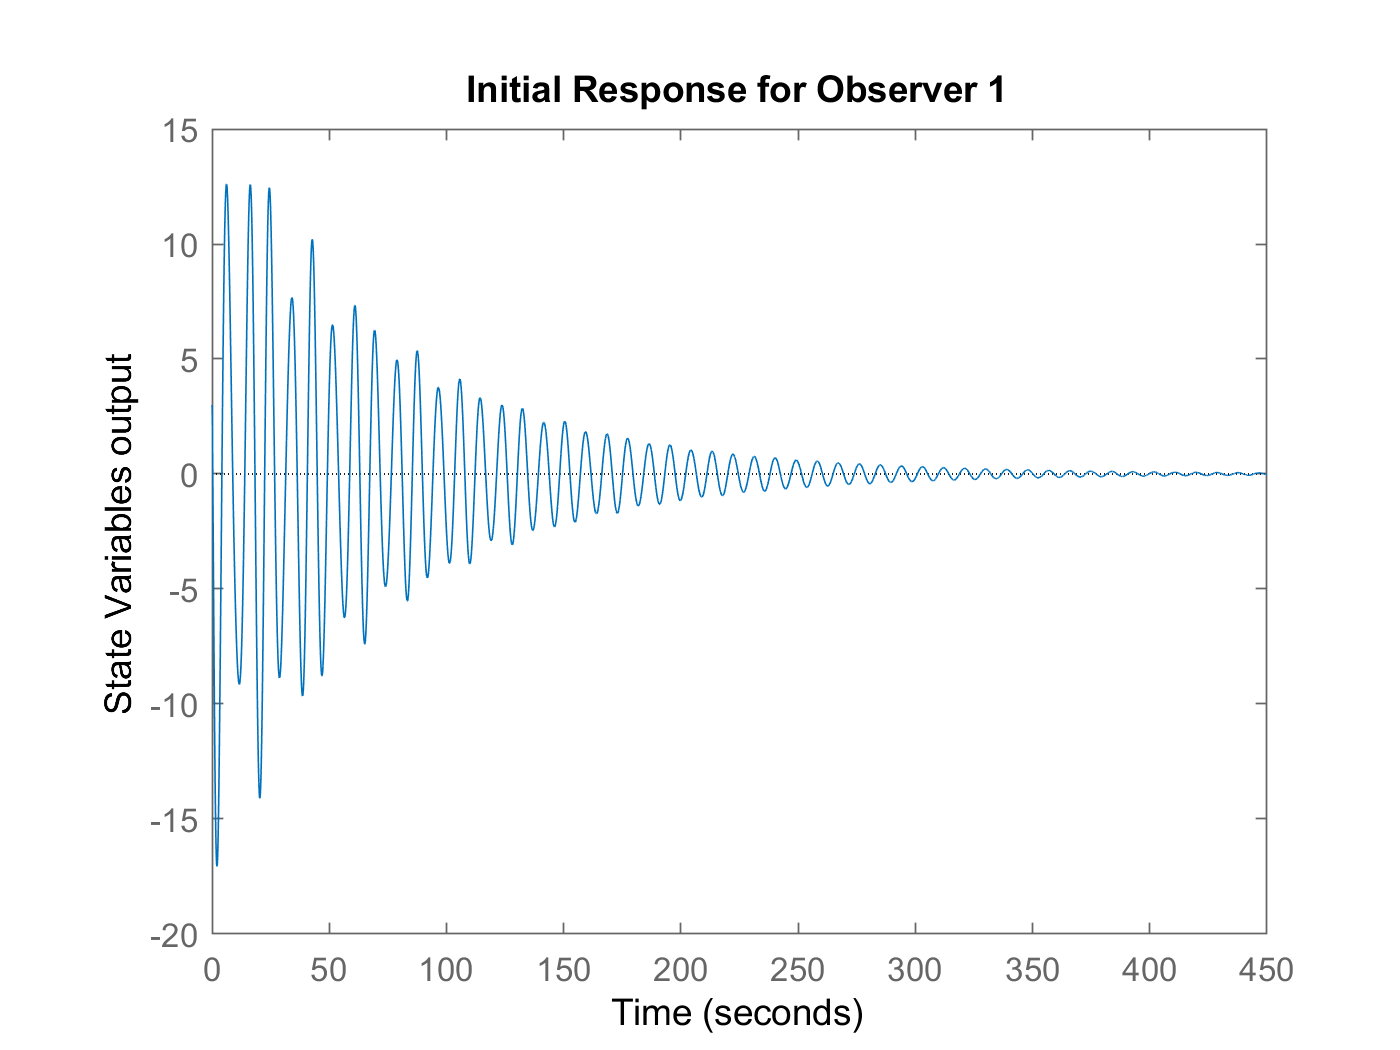

figure
initial(statespace1,initial_state)
title('Initial Response for Observer 1')
xlabel('Time')
ylabel('State Variables output')

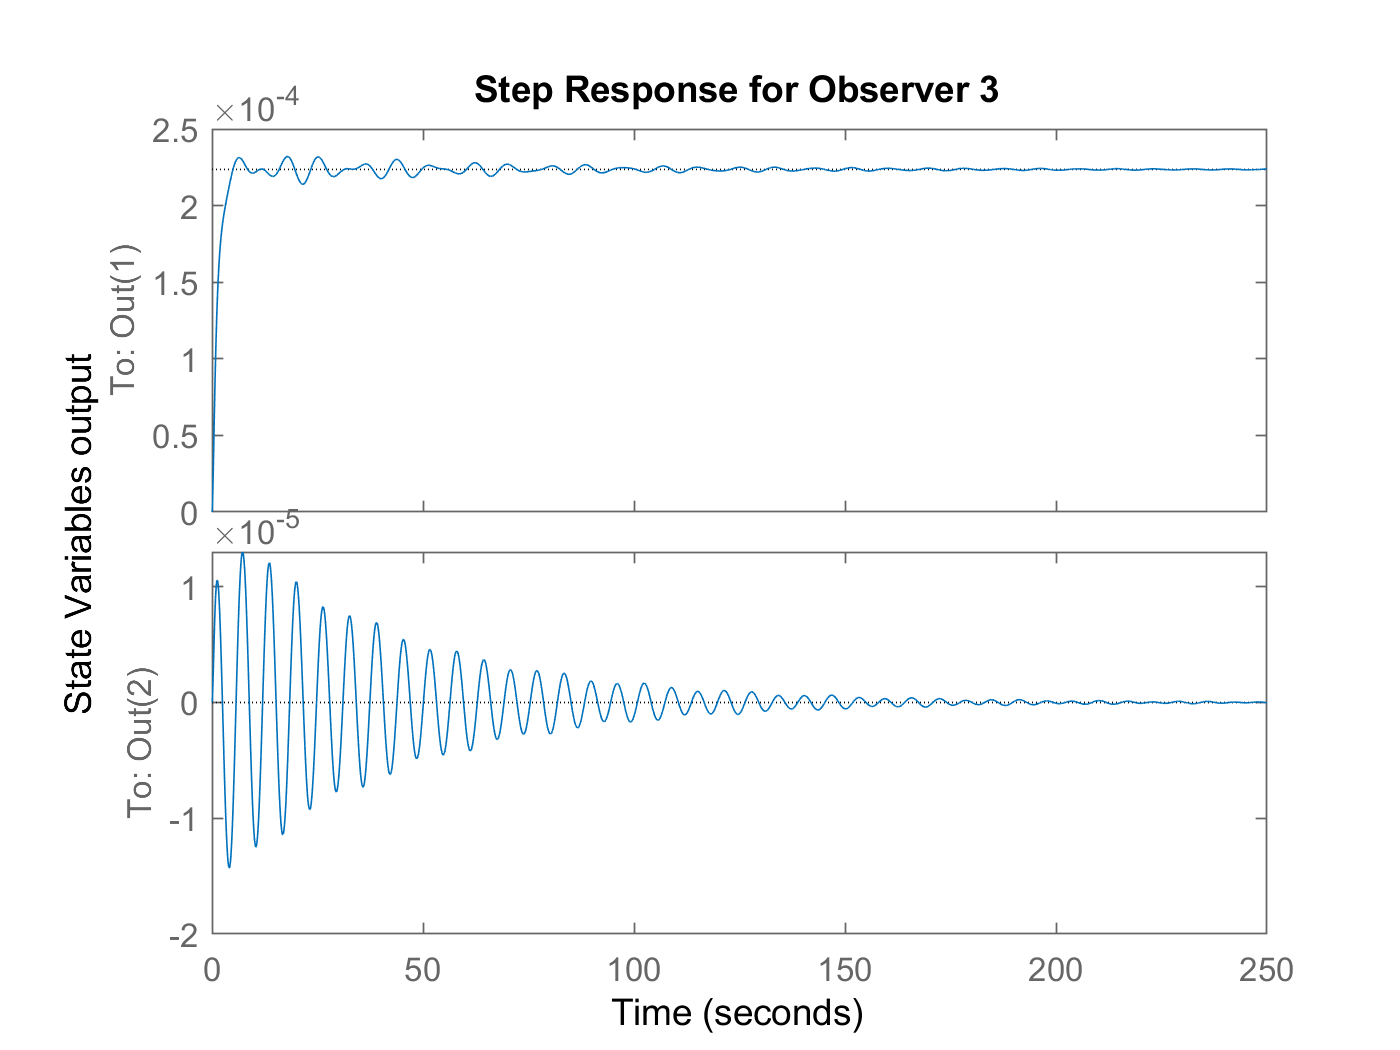

figure
step(statespace3)
title('Step Response for Observer 3')
xlabel('Time')
ylabel('State Variables output')

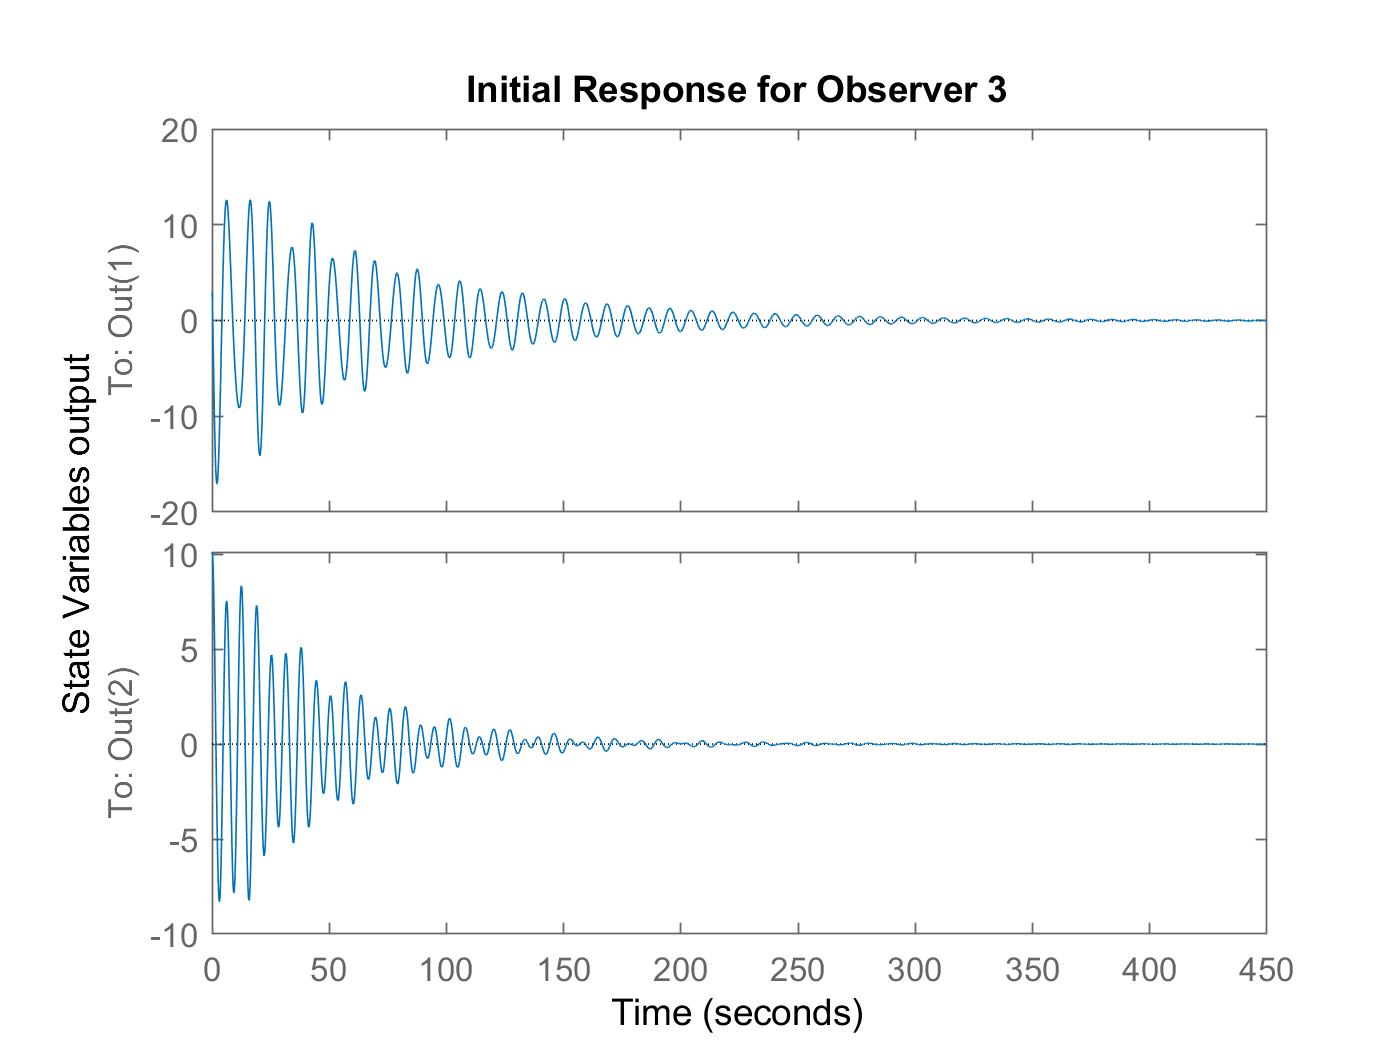

figure
initial(statespace3,initial_state)
title('Initial Response for Observer 3')
xlabel('Time')
ylabel('State Variables output')

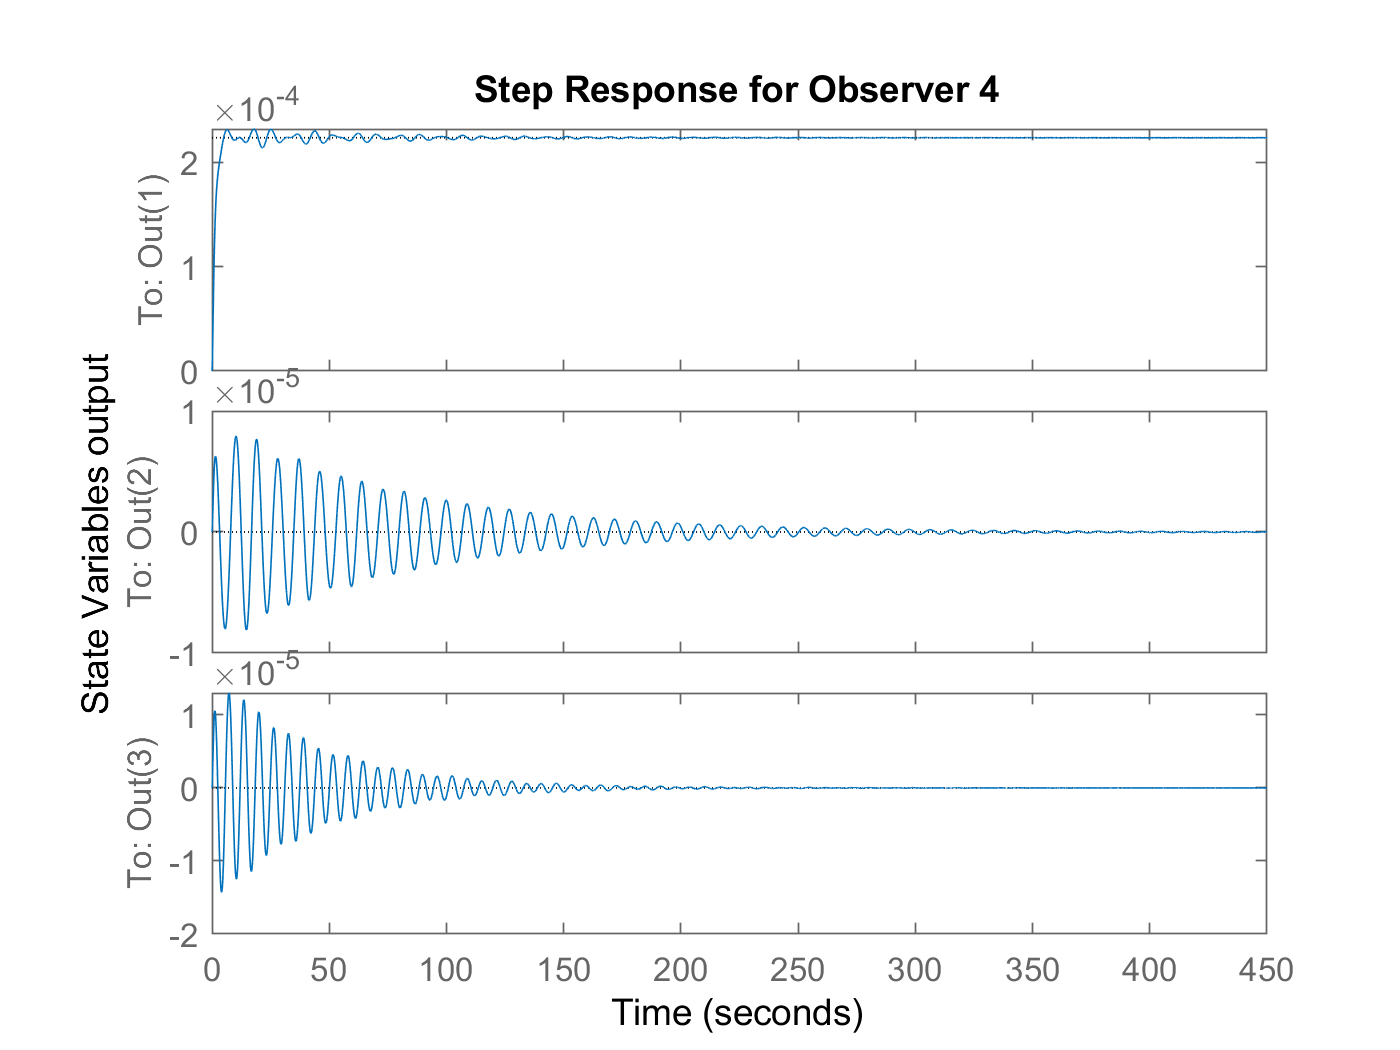

figure
step(statespace4)
title('Step Response for Observer 4')
xlabel('Time')
ylabel('State Variables output')

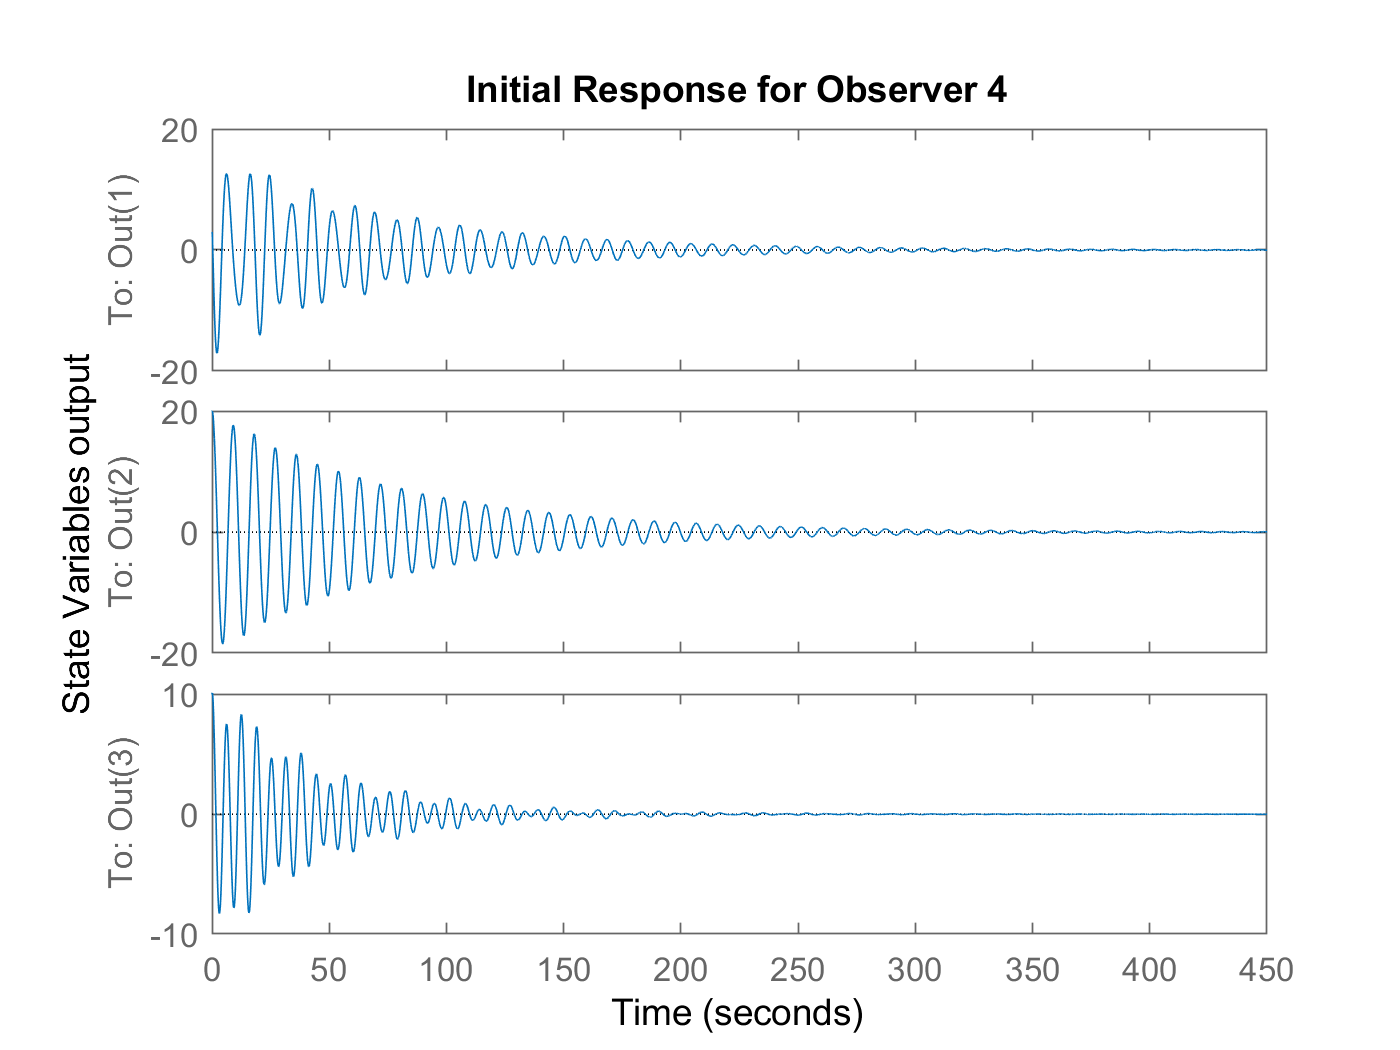

figure
initial(statespace4,initial_state)
title('Initial Response for Observer 4')
xlabel('Time')
ylabel('State Variables output')

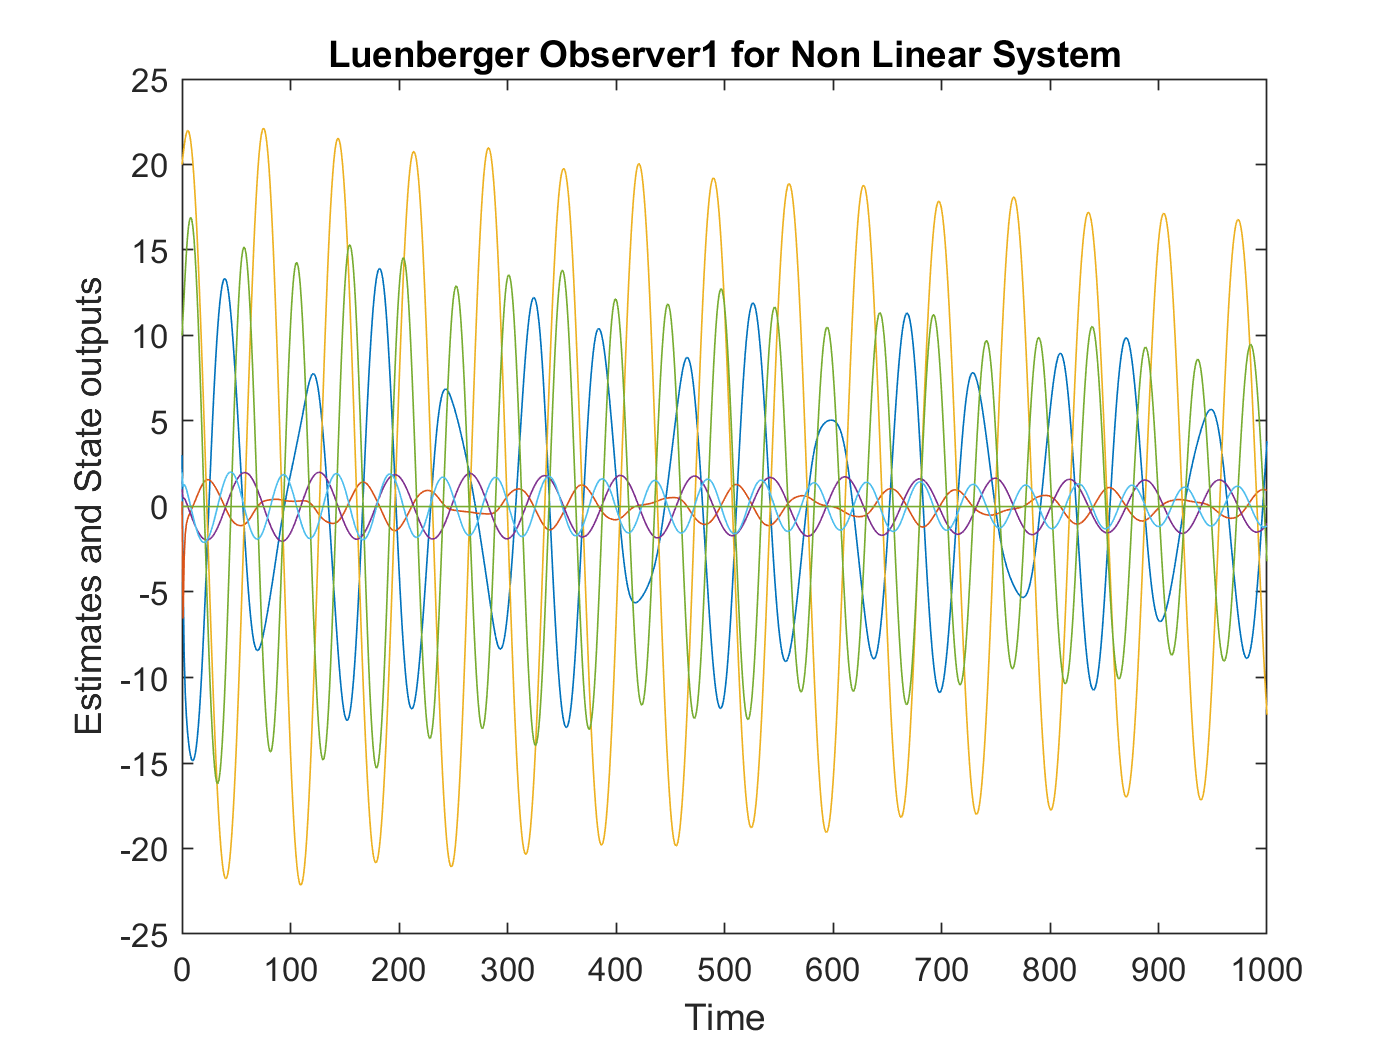

%Luenberger Observer for Non Linear System Model:
%Note that we are plotting the estimates. We are not not plotting the
%error

simulation_time = 0:1:1000;
[time,out] = ode45(@ode45_callback_luenberger_1,simulation_time,initial_state);
figure
plot(time,out)
title('Luenberger Observer1 for Non Linear System')
xlabel('Time')
ylabel('Estimates and State outputs')

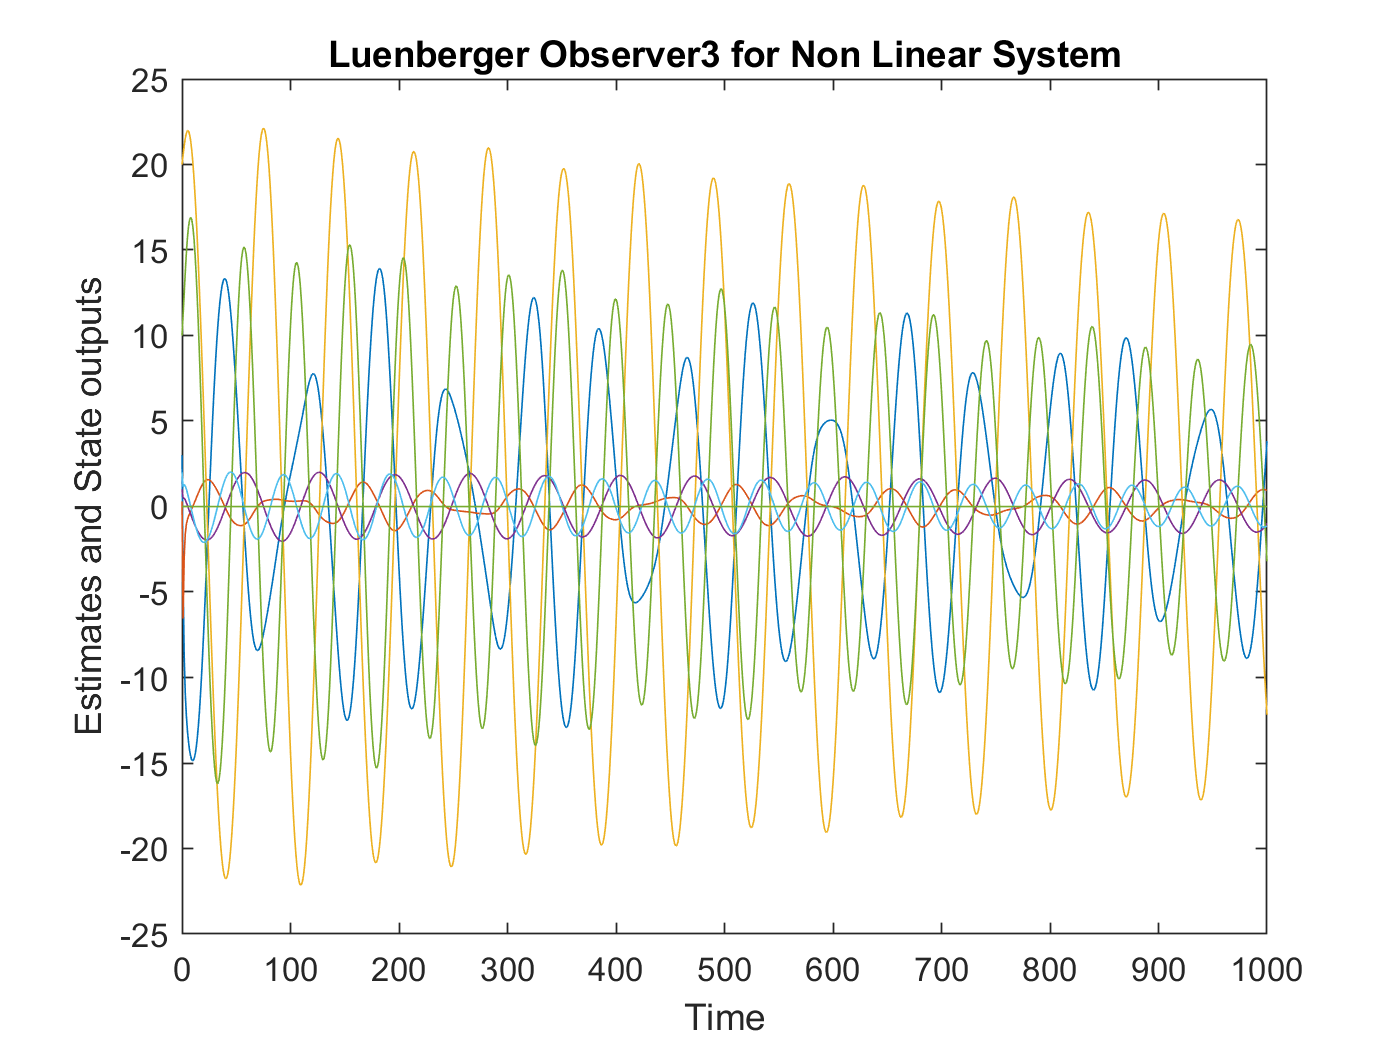

[time,out] = ode45(@ode45_callback_luenberger_2,simulation_time,initial_state);
figure
plot(time,out)
title('Luenberger Observer3 for Non Linear System')
xlabel('Time')
ylabel('Estimates and State outputs')

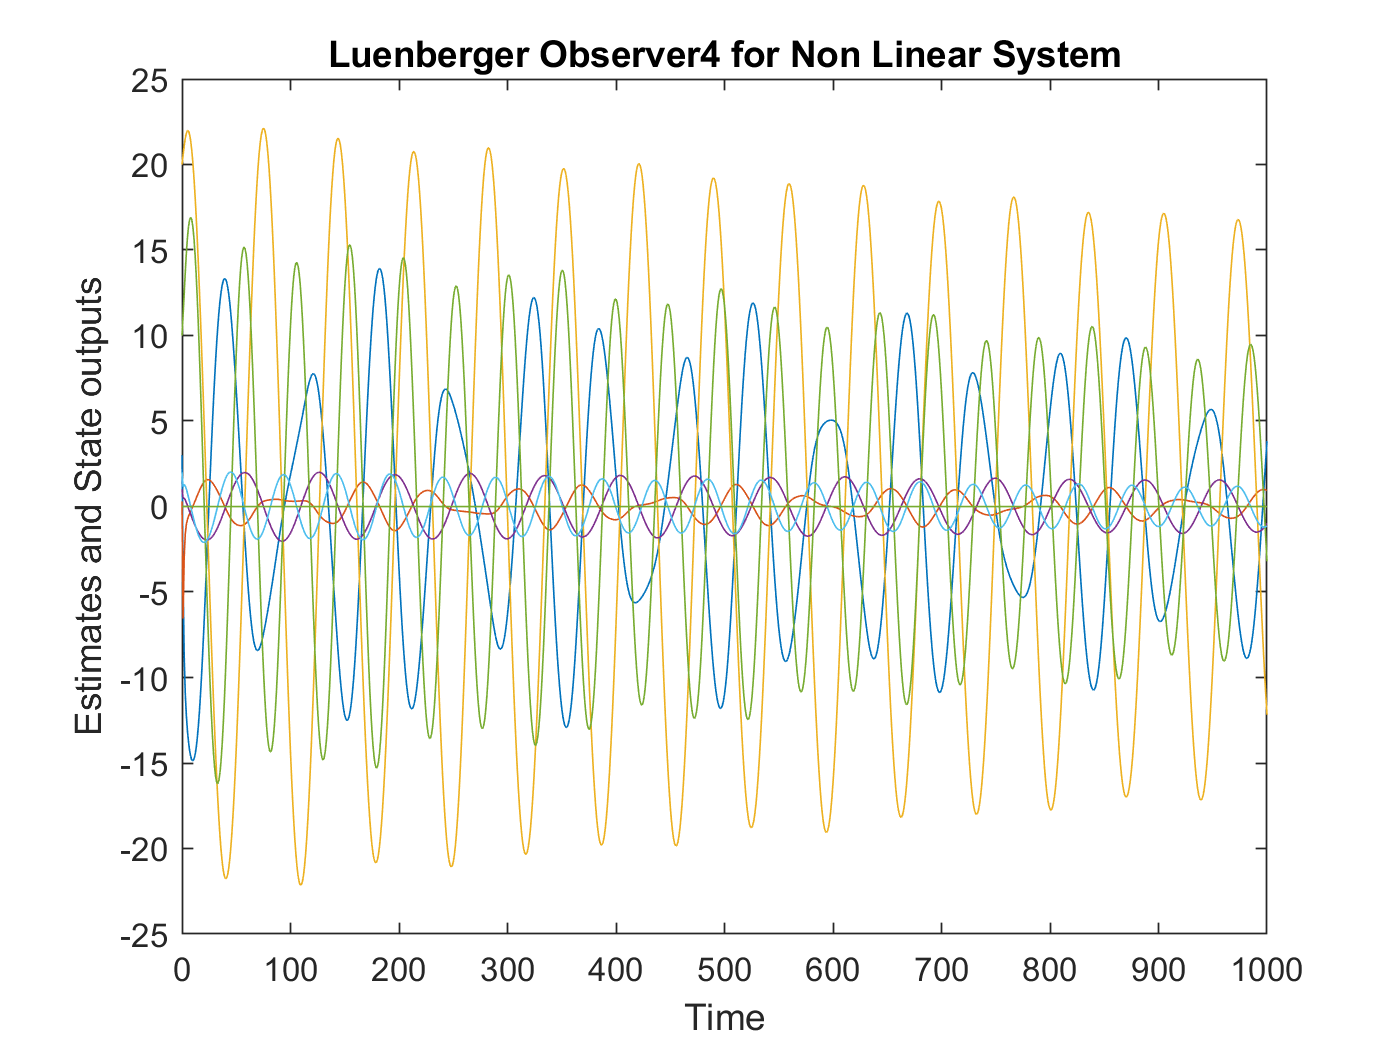

figure
[time,out] = ode45(@ode45_callback_luenberger_3,simulation_time,initial_state);
plot(time,out)
title('Luenberger Observer4 for Non Linear System')
xlabel('Time')
ylabel('Estimates and State outputs')